%Refer %https://au.mathworks.com/help/phased/ref/rotx.html for how the
%rotation matrix work

%Refer
%https://au.mathworks.com/help/supportpkg/android/ref/orientation.html for
%the axes details of the smartphone

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc
clear
%Reading the measurement files collected using Matlab mobile
route=['C:\Users\qyu38\MATLAB Drive\MobileSensorData\\4b.mat'];
data=load([route])

data = struct with fields:
    Acceleration: [4658×3 timetable]
     Orientation: [4658×3 timetable]



%extract the name of original data file 
test=split(route,'\');
test=test(end);
test=split(test,'.');
test_name=test(1);

%%extract the sensor data 
t_acc=data.Acceleration.Timestamp; 
% t_gyr=data.AngularVelocity.Timestamp; 
% gyr=AngularVelocity.Variables;

## Rotation matrix

%store the measurements into a dataframe
l_v_all=[data.Acceleration.X'; data.Acceleration.Y'; data.Acceleration.Z'];
angle=[data.Orientation.Y';data.Orientation.Z';data.Orientation.X']; %pitch; roll and yaw
[lc_x,lc_y,lc_z] = nam_xyz(l_v_all);

figure
%plot original acceleration
subplot(3,2,1);
plot(t_acc,lc_x);%plot x
ylabel('x')

title('local');
subplot(3,2,3)
plot(t_acc,lc_y);%plot y
ylabel('y')

subplot(3,2,5)
plot(t_acc,lc_z);%plot z 
ylabel('z')

%ensure the size of acceleration and angle matrix match
[l_v_all,angle,t_acc] = consistent_dimension(l_v_all,angle,t_acc);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% this section is
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% critical
%mirror the measurements when the screen is facedown, identify the screen
%facedown using the z-axis acceleration value
for item=1:length(l_v_all(3,:))
    if l_v_all(3,item)<0
        angle(2,item)=angle(2,item)+180;
        l_v_all(3,item)=-l_v_all(3,item);
        l_v_all(1,item)=-l_v_all(1,item);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

g_v_all=zeros(size(l_v_all)); %create a placeholder or global vectors

%reoritent the measurements to the global system
for col = 1 : width(l_v_all)
    g_v=three_D_reorient(l_v_all(:,col),angle(1,col),angle(2,col),angle(3,col));%g_v=three_D_reorient(l_v,pitch,roll,yaw) corresponding columns
    g_v_all(:,col)=g_v;
end

## Plot reoriented accelerations

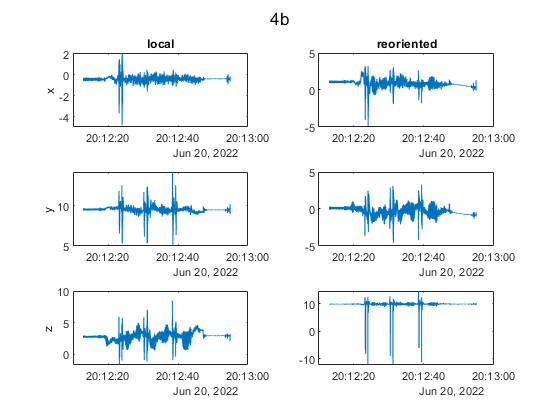

[gl_x,gl_y,gl_z] = nam_xyz_glb(g_v_all);
%plot reoritented acceleration
subplot(3,2,2)
plot(t_acc,gl_x);%plot x
title('reoriented');

subplot(3,2,4)
plot(t_acc,gl_y);%plot y

subplot(3,2,6)
plot(t_acc,gl_z);%plot z

sgtitle(test_name); 

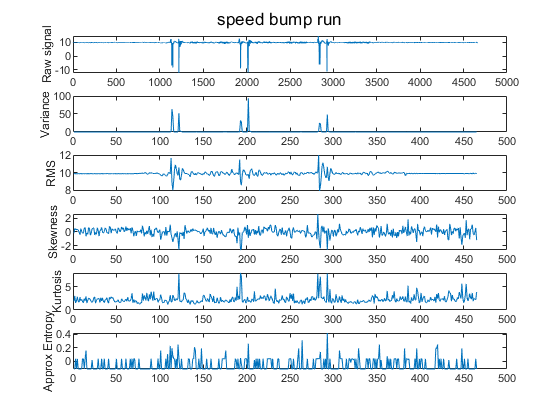


%plotting the time domain features
n=10;
[gl_z_seg] = parition(gl_z,n);
plot_td_features(gl_z_seg,gl_z,'speed bump run')